# EKF tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
17-Aug-2025 19:16:43: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 8 workers.


p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 8 parallel workers

## Define optimization variables

var1 = optimizableVariable('qi', [1e-2, 1e0], 'Transform', 'log');
var2 = optimizableVariable('qF', [1e-5, 1e-3], 'Transform', 'log');
var3 = optimizableVariable('qw', [1e2, 1e4], 'Transform', 'log');

optimization_variables = [var1, var2, var3];
nVars = size(optimization_variables, 2);

a=[0.49676    0.00067914    979.82];
a=[0.60115    0.00099045    7978.6];
a=[0.27401    0.00042419    993.27];
log10(a)

ans =    -0.5622   -3.3724    2.9971


## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = KF_simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |           qi |           qF |           qw |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       1 | Accept |  0.00036418 |      2.7954 |  0.00033904 |  0.00033929 |      0.43392 |   3.3605e-05 |       153.86 |
|    2 |       1 | Accept |  0.00035752 |       2.364 |  0.00033904 |  0.00033929 |      0.30744 |   3.0639e-05 |       215.56 |
|    3 |       1 | Accept |  0.00034682 |      2.3542 |  0.00033904 |  0.00033929 |     0.015069 |    6.409e-05 |       133.73 |
|    4 |    

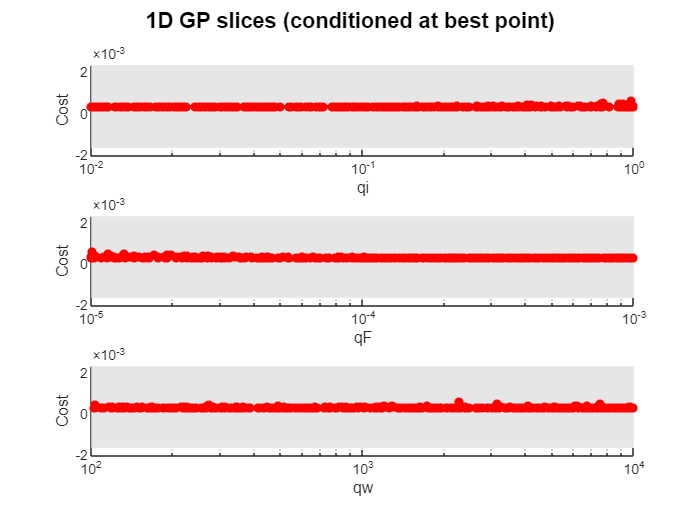

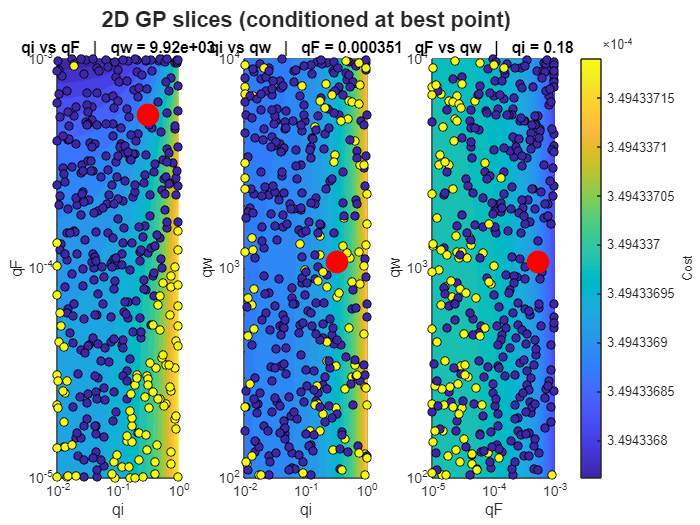

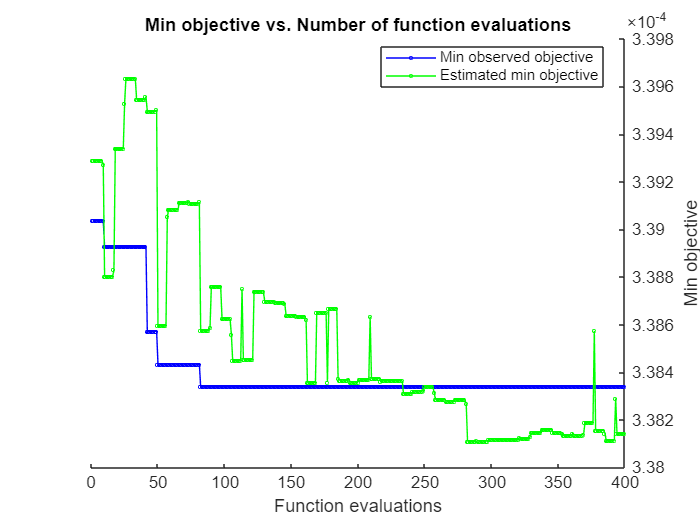

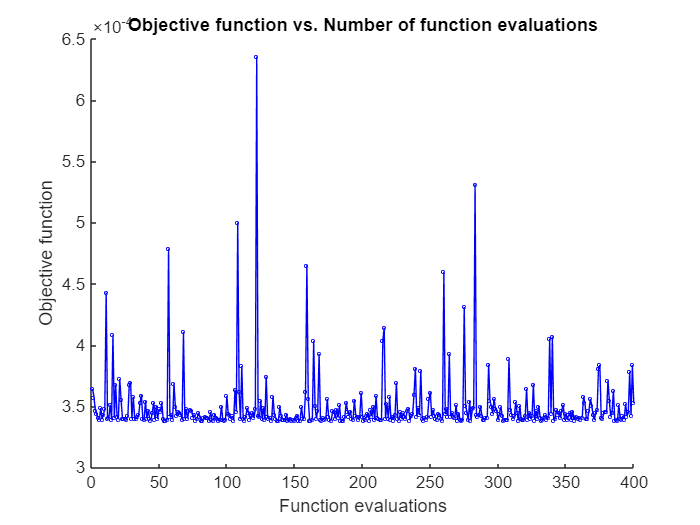

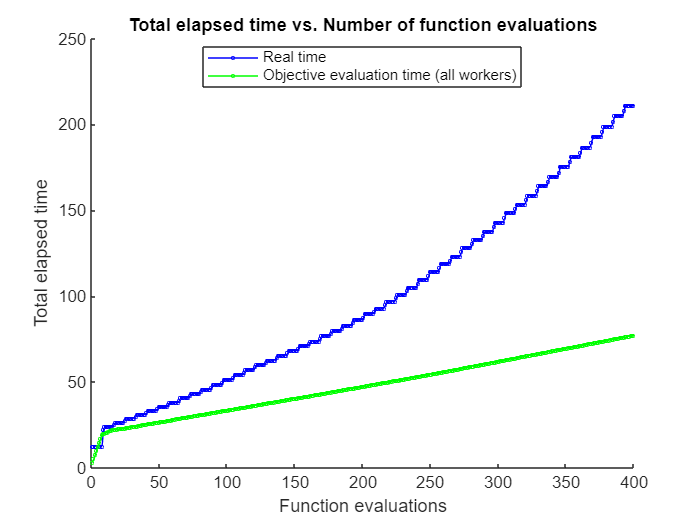

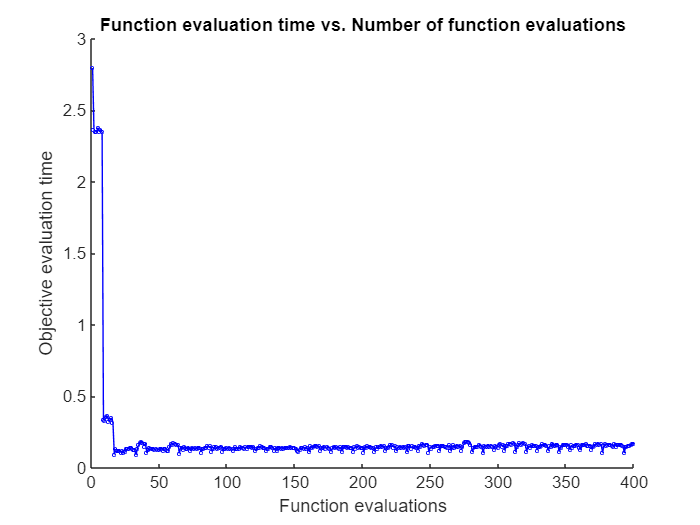


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 400 reached.
Total function evaluations: 400
Total elapsed time: 211.1837 seconds
Total objective function evaluation time: 77.1226

Best observed feasible point:
      qi           qF          qw  
    _______    __________    ______
    0.32113    0.00054349    1072.8
Observed objective function value = 0.00033834
Estimated objective function value = 0.00033901
Function evaluation time = 0.13068

Best estimated feasible point (according to models):
      qi           qF          qw  
    _______    __________    ______
    0.18031    0.00035145    9919.1
Estimated objective function value = 0.00033814
Estimated function evaluation time = 0.14527



limits = vertcat(optimization_variables.Range);
lb = log10(limits(:, 1).');
ub = log10(limits(:, 2).');

NumSeedPoints = 10*p.NumWorkers;
Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {optimization_variables.Name});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   50*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

sorted_Trace = 400×4 table
      qi           qF          qw         Cost   
    _______    __________    ______    __________
    0.32113    0.00054349    1072.8    0.00033834
    0.50741    0.00099843    8452.8    0.00033834
    0.47291    0.00098238    7924.6    0.00033834
    0.59929    0.00097426    7791.2    0.00033835
    0.66357    0.00099784    9243.5    0.00033837
     0.6396    0.00077935    1774.8    0.00033837
    0.29982    0.00071787    7048.8    0.00033839
    0.34931    0.00099382    7372.4    0.00033841
    0.27879    0.00051596    8789.9    0.00033841
    0.21499    0.00044095    2402.9    0.00033841
    0.88132    0.00096226    3011.5    0.00033843
    0.45894      0.000623    8607.2    0.00033843
    0.93699    0.00099369    2474.6    0.00033844
    0.20124    0.00040755    3738.5    0.00033844
     0.1686    0.00032959    1630.8  

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

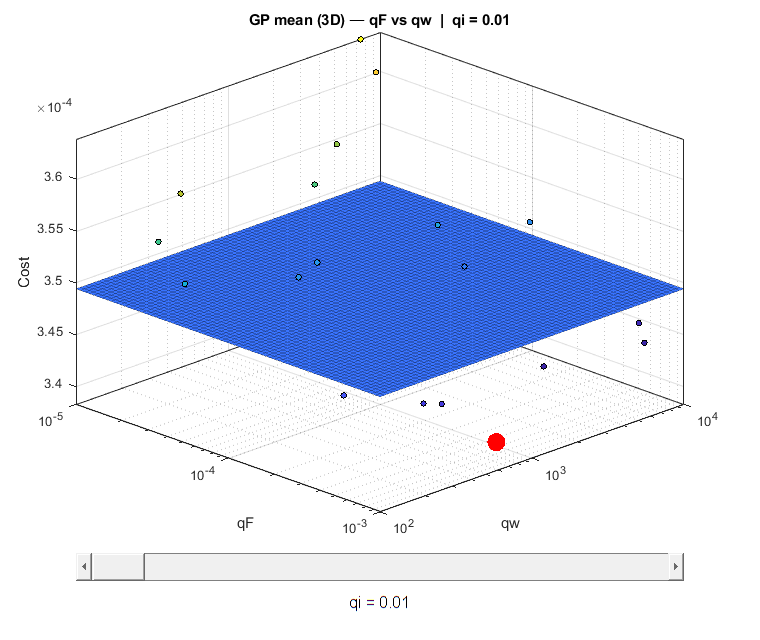

plotGP(gp, results, 'qF', 'qw')

## Sensitivity analysis

Global (trained kernel length scales)

A smaller lenght scale denotes a more important variable

lengthScales = gpGlobalSensitivity(gp)

lengthScales =    22.6643   23.5151   23.2870


Local (model gradient)

x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)

gradMu = 1.0e-19 *

   -0.0001   -0.0000    0.2771


gradSigma2 = 1.0e-33 *

   -0.0197    0.0000   -0.7687
